# WLAN MAC Basics - Scheduling actions

- Generate beacon frames only

- Display some kind of infomation whenever network simulator advances to a new event

Copyright 2024-2025 The MathWorks, Inc

clear all;
clc;
format shortEng;

### Physical constants and environment

networkSimulator = wirelessNetworkSimulator.init;

### AP

band                = 5;
channel             = 36;
channelBandwidth    = 20e6;
fc                  = wlanChannelFrequency(channel,band);
TU                  = 1024e-6

TU =      1.0240e-003


simulationDuration  = 10*TU

simulationDuration =     10.2400e-003


txPower = 0.0;
txGain  = 0.0;

### Geometry

APPosition  = [0,0,0];
STAPosition = [5.0, 0.0, 0.0];

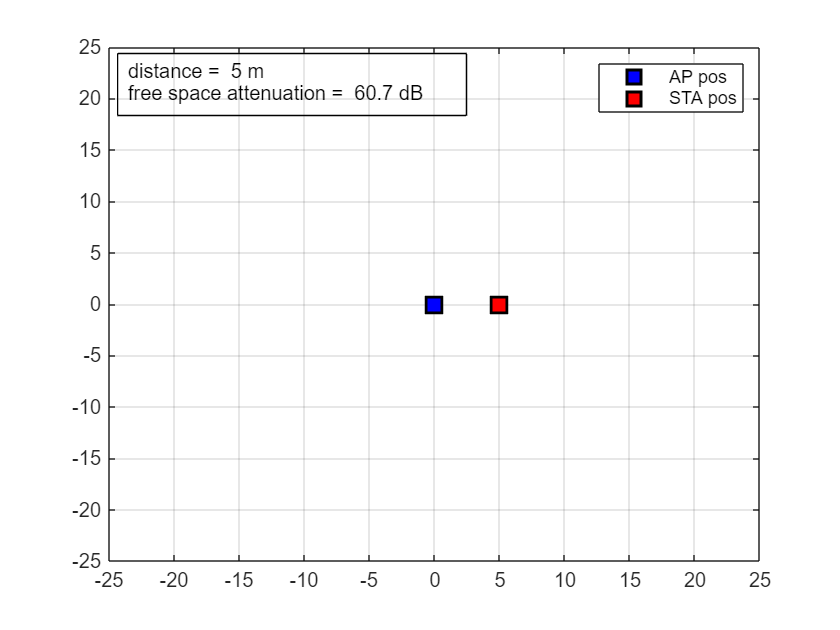

plotStations (APPosition, STAPosition, fc);

### Create AP

- 802.11n type

APCfg = wlanDeviceConfig(...
    "Mode","AP",...
    "TransmissionFormat","HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",channelBandwidth,...
    "TransmitPower", txPower, ...
    "TransmitGain",txGain, ...
    "MCS",3, ...
    "BeaconInterval",1, ...
    "InitialBeaconOffset",0);

AP = wlanNode(...
    "Name","AP",...
    "Position",APPosition, ...
    "DeviceConfig",APCfg,...
    "MACFrameAbstraction",false,...
    "PHYAbstractionMethod","tgax-evaluation-methodology");

### Create STA

STACfg = wlanDeviceConfig(...
    "Mode","STA",...
    "TransmissionFormat","HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",channelBandwidth,...
    "TransmitPower",txPower, ...    
    "MCS",3);

STA = wlanNode(...
    "Name","STA",...
    "Position",STAPosition, ...
    "DeviceConfig",STACfg,...
    "MACFrameAbstraction",false,...
    "PHYAbstractionMethod","tgax-evaluation-methodology");

### Add random mobility on STA

addMobility(STA,...
    'BoundaryShape', "circle",...
    'SpeedRange', [0.1,10]);

### Associate AP with STA

associateStations(AP,STA)

addNodes(networkSimulator,{AP, STA})

### Action Scheduling

- Do something when NetworkSimulation Time advances

startTime   = 0;
periodicity = 0;

% Periodic, TimeAdvance, OneTime

userData = struct( ...
    ActionType  = "TimeAdvance", ...
    Simulator   = networkSimulator);

actionID = scheduleAction(networkSimulator,@onTimeAdvance,userData,startTime,periodicity);

%networkSimulator.Nodes{1}

#### Run the simulation

event#001	 time = 16.00 us	 dt = 16.00 us	 txPackets = 0	 X = 5.00	 Y = -0.000080
event#002	 time = 34.00 us	 dt = 18.00 us	 txPackets = 0	 X = 5.00	 Y = -0.000169
event#003	 time = 54.00 us	 dt = 20.00 us	 txPackets = 1	 X = 5.00	 Y = -0.000269
event#004	 time = 366.00 us	 dt = 312.00 us	 txPackets = 1	 X = 5.00	 Y = -0.001821
event#005	 time = 382.00 us	 dt = 16.00 us	 txPackets = 1	 X = 5.00	 Y = -0.001901
event#006	 time = 384.00 us	 dt = 2.00 us	 txPackets = 1	 X = 5.00	 Y = -0.001911
event#007	 time = 400.00 us	 dt = 16.00 us	 txPackets = 1	 X = 5.00	 Y = -0.001990
event#008	 time = 409.00 us	 dt = 9.00 us	 txPackets = 1	 X = 5.00	 Y = -0.002035
event#009	 time = 427.00 us	 dt = 18.00 us	 txPackets = 1	 X = 5.00	 Y = -0.002124
event#010	 time = 445.00 us	 dt = 18.00 us	 txPackets = 1	 X = 5.00	 Y = -0.002214
event#011	 time = 499.00 us	 dt = 54.00 us	 txPackets = 1	 X = 5.00	 Y = -0.002483
event#012	 time = 1024.00 us	 dt = 525.00 us	 txPackets = 1	 X = 4.99	 Y = -0.005095
event#

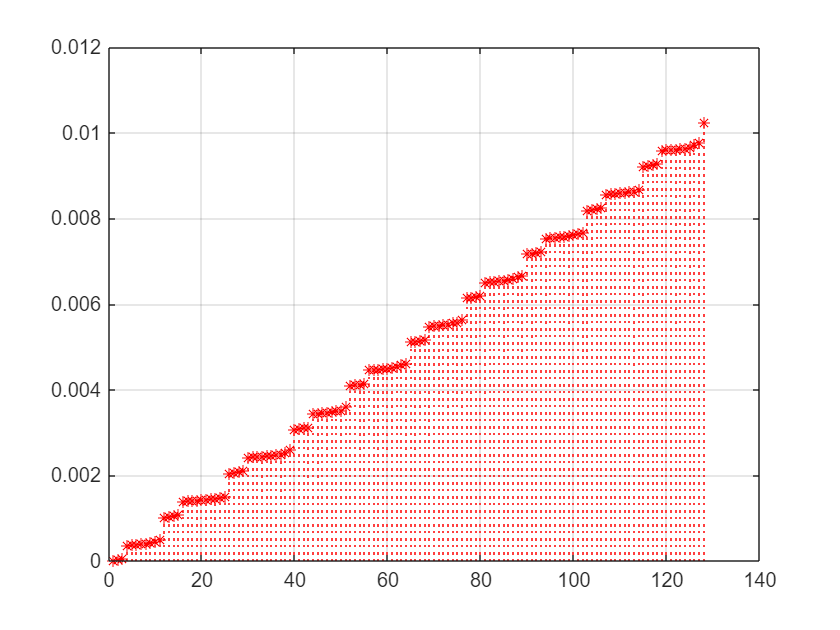

run (networkSimulator,simulationDuration)

### Visualize statistics

APStatistics  = statistics(AP);
STAStatistics = statistics(STA);

APStatistics.Name;
APStatistics.MAC.TransmittedBeaconFrames

ans =     10.0000e+000


APStatistics.MAC.TransmittedBeaconFrames

ans =     10.0000e+000


STAStatistics.MAC.ReceivedBeaconFrames

ans =     10.0000e+000


Count the number of times the function is called

function onTimeAdvance(~,userData)

    persistent counter; 
    persistent previousTime;
    persistent curTimeVec;
    
    if isempty(counter)
        counter = 1;
    end

    if isempty(previousTime)
        previousTime = 0;
    end

    if isempty(curTimeVec)
        curTimeVec = NaN(256,1);        
        stem(curTimeVec, 'r*');
        grid on;
    end

    STAName = userData.Simulator.Nodes{2}.Name;    
    STA_Xpos = userData.Simulator.Nodes{2}.Position(1);    
    STA_Ypos = userData.Simulator.Nodes{2}.Position(2);        
    %disp(counter);    
    
    curTime = userData.Simulator.CurrentTime;    
    curTimeVec(counter) = curTime;    
    
    deltaT          = curTime - previousTime;
    previousTime    = curTime;        

    % get number of tx packets at time t = curTime
    numTxPackets = userData.Simulator.Nodes{1}.statistics.PHY.TransmittedPackets;
    
    % plot current time
    stem(curTimeVec, 'r*:');    
    grid on;
    
    fprintf("event#%03d\t time = %.2f us\t dt = %.2f us\t txPackets = %d\t X = %.2f\t Y = %.6f\n", counter, curTime*1e6, deltaT*1e6, numTxPackets, STA_Xpos, STA_Ypos);
    
    % increment counter
    counter = counter + 1;
end